# INTERPOLACJA I APROKSYMACJA

## Ogólne zagadnienia wymagane na laboratorium nr 3

## "Wstęp do metod numerycznych'

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Rigth"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

**Umiejętności wymagane na laboratorium**

Na laboratorium wymagany jest cały zakres wiedzy wykładowej ze szczególnym uwzględnieniem tematyki interpolacji i aproksymacji. W podstawowym zakresie sprawdzane będzie:

- Czy student zna postać kanoniczną problemu numerycznego p.t. "Interpolacja" i "Aproksymacja"? Czy potrafi określić formę danych wejściowych i formę danych wyjściowych dla tych problemów?

- Czy student potrafi przeprowadzić interpolację i aproksymację wielomianową?

- Czy student rozumie problem związany z jakością interpolacji/aproksymacji wielomianowej - zachowanie błędu poza węzłami interpolacji wraz ze wzrostem stopnia wielomianu interpolacyjnego?

- Czy student rozumie co to jest interpolacja typu spline, czy potrafi określić jej zalety/wady w stosunku do zwykłej interpolacji?

- Czy student rozumie zależność między właściwościami funkcji interpolowanej a zachowaniem funkcji interpolujących?

- Czy student rozumie czym jest transformata DFT i jej implementacja w postaci FFT?

Docelowo student powinien orientować się jakie ogólne właściwości mają poznane metody w świetle wszystkich problemów wymienionych powyżej. W związku z tym, że na właściwościach interpolacji wielomianowej opera się wiele zaawansowanych metod kluczowym zagadnieniem jest zachowanie się błędu interpolacji w funkcji ilości danych wejściowych w różnych rodzajach interpolacji. Będzie to sprawdzane na laboratorium.

# PODPOWIEDZI IMPLEMENTACYJNE

## **Reprezentacja wielomianów w MATLAB**

Należy pamiętać, że w MATLAB wielomiany mogą być reprezentowane w specjalny sposób w postaci wektora współczynników od największego do najmniejszego. Przykładowo wektor:

A = [1 2 3 0 5];

może zostać zinterpretowany jako wielomian:


$$A=x^4+2x^3+3x^2+5$$


Największa potęga wynosi 4 ponieważ wektor A ma 5 elementów (piąty jest czynnik x^0=1 czyli czynnik stały). Zwróć uwagę mimo, że w wielomianie nie występuje czynnik liniowy to musi on być zapisany w wektorze jako 0 żeby interpretacja wektora jako wielomianu się udała, czyli *de facto*:


$$A=x^4+2x^3+3x^2+0x+5$$


Taki zapis wielomianów jest bardzo wygodny w użytkowaniu. na takim zapisie wielomianów działają funkcje, których nazwy zaczynają się od ***poly...*** np.:

- ***polyint()*** - zwraca wektor współczynników wielomianu będącego całką z wielomianu wejściowego

- ***polyder()*** - zwraca wektor współczynników wielomianu będącego pochodną z wielomianu wejściowego

- ***polyval()*** - zwraca wartości wielomianu opisanego współczynnikami w wybranych punktach

- ***polyfit()*** - wykonuje interpolację bądź aproksymację wielomianową, zwracając wynik w postaci wektora współczynników wielomianu

% Przykładowo 


A_calka =      2.000000000000000e-01     5.000000000000000e-01     1.000000000000000e+00                         0     5.000000000000000e+00                         0


A = [1 2 3 0 5];

Wielomian: $A=x^4+2x^3+3x^2+5$

A_calka = polyint(A)

A_pochodna =      4     6     6     0


Czyli wielomian: $A_{calka}=\frac{1}{5}x^5+\frac{1}{2}x^4+1x^3+0x^2+5x+0$

A_pochodna = polyder(A)

Czyli wielomian: $A_{pochodna}=4x^3+6x^2+6x+0$

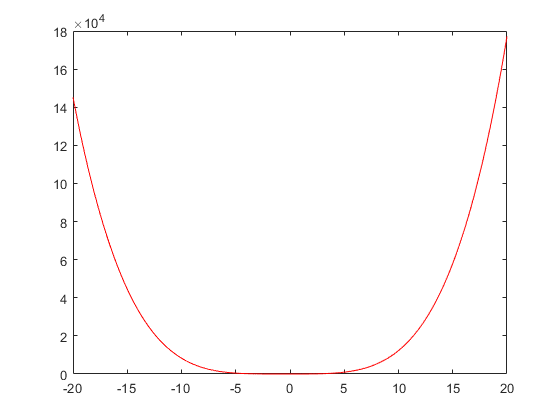

% Jeżeli byśmy chcieli wyrysować wielomian A to mozemy zrobić to tak:


x=[-20:0.01:20];

plot(x,polyval(A,x),'r');
 

## Interpolacja wielomianowa

Podstawowy sposób interpolacji wielomianowej w MATLAB polega na zastosowaniu funkcji ***polyfit()***, która buduje i rozwiązuje układ równań liniowych dla dostarczonego problemu. Układ ten nie musi być określony (nie musi zawierać tyle samo równań co niewiadomych), ale może być również układem nadokreślonym (więcej równań niż niewiadomych). Wiedząc jak powstają układy równań rozwiązywane w zagadnieniu interpolacji można się domyśleć, czy to czy układ będzie miał charakter układu równań określonych (i w konsekwencji wynikiem będzie rozwiązanie problemu interpolacji), czy nadokreślonym (i w konsekwencji wynikiem będzie rozwiązanie problemu aproksymacji). Steruje tym argument podawany do funkcji ***polyfit()*** w postaci stopnia wielomianu dla jakiego ma być zbudowany układ równań interpolacyjnych/aproksymacyjnych.

Ciekawostką może być fakt w jaki sposób budowany jest ten układ. Do jego budowy brany jest bowiem podstawowy ciąg wielomianów w postaci naturalnej tworzący w konsekwencji macierz Vandermonda w postaci:

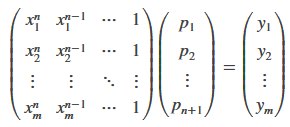

O tej macierzy mówiliśmy, że jest źle uwarunkowana numerycznie w odniesieniu do zagadnienia rozwiązywania układów równań linowych. Takie podejście jest jednak całkowicie poprawne numerycznie o ile rozumie się czym jest dokładnie uwarunkowanie numeryczne i jaki ma związek z rozmiarem problemu, jak powstają takie macierze w zagadnieniu interpolacji/aproksymacji i jakie są właściwości prostych interpolacji/aproksymacji wielomianowych.

Przykładowy kod realizujący prosta interpolację wielomianową:

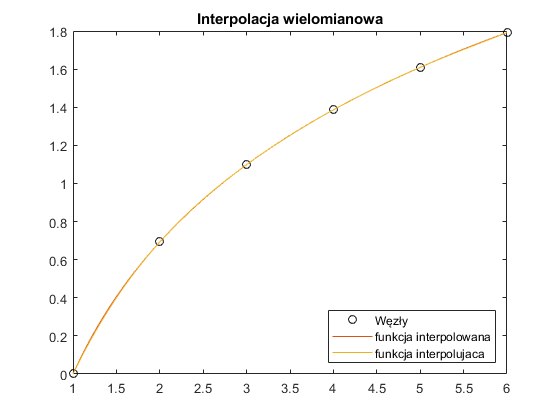

clear all;
% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 
x = [1:1:6];
y = log(x);           %zatem funkcja interpolowana to ln(x)

%Wyliczenie współczynników wielomianu interpolacyjnego
wsp = polyfit(x,y,numel(x)-1);

%Chcemy teraz narysować funkcję interpolującą, ale również poza węzłami
%więc musze stworzyć nowy wektor x, gęstszy używany do rysowania
xx = [min(x):0.01:max(x)];
yy = polyval(wsp,xx);

%Narysujmy funkcję, węzły i wielomian interpolujący
plot(x,y,'ko');
hold on;
plot(xx,log(xx));
plot(xx,yy)
hold off;

%Na koneic trochę opisu co jest co
legend("Węzły", "funkcja interpolowana", "funkcja interpolujaca", 'Location','southeast')
title("Interpolacja wielomianowa");

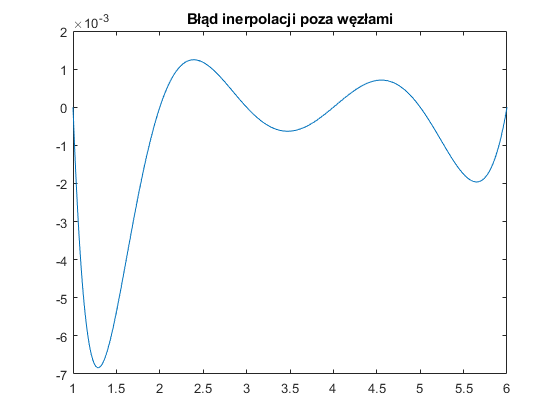

%Policzmy błąd interpolacji - oczywiście poza węzłami bo w węzłach nas nie
%interesuje bo z definicji problemu wynosi 0:

blad = yy-log(xx);

%I wykreślmy ten błąd:
plot(xx,blad);
title("Błąd inerpolacji poza węzłami");

%Skrypt jest zaimplementowany w automatyczny sposób, możesz pobawić się
%funkcjami i ilością węzłów. Zwróć uwagę na pojawiające się warningi
%MATLABA. Czy potrafisz powiedzieć o czym informują?


 

Ciągi wielomianów o jakich mówlimy na wykładzie nie są jawnie implementowane w MATLAB (wchodzą w skład innych, większych metod), więc możesz zostać poproszony o jawne zaimplementowanie funkcji wykonujacej interpolację za pomocą jednego z podanych ciągłów, analogicznej do funkcji ***polyfit()***. Jej zadaniem byłoby zbudowanie odpowiedniej macierzy i jej rozwiązanie za pomocą metody wbudowanej MATLAB. 

## INNE RODZAJE INTERPOLACJI W MATLAB

Bardziej zaawansowane implementacje metod interpolacyjnych w MATLAB są zaimplementowane m.in. za pomocą funkcji ***interp1()***. Ta funkcja może implementować w sobie wiele metod, w tym metod interpolacji wielomianowej, opartej o podział na podprzedziały - metody nazwane zbiorczo splinami. Przyjrzyjmy się tym metodom:

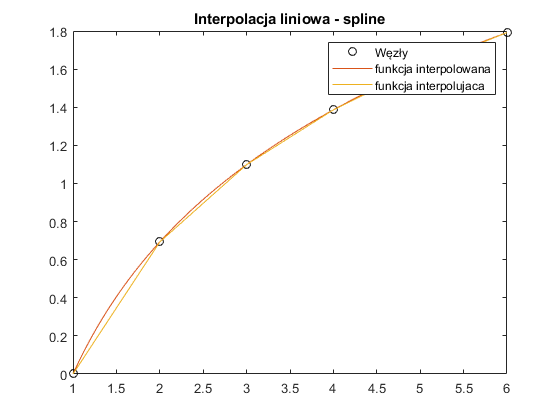

% Podstawowa interpolacja to interpolacja liniowa:
clear all;

% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 
x = [1:1:6];
y = log(x);           %zatem funkcja interpolowana to ln(x)
xx = [min(x):0.01:max(x)];

%Zwróć uwagę, że składnia jest trochę inna. Tutaj nie mamy jawnie
%współczynników, tylko od razu wynik interpolacji
yy = interp1(x,y,xx);

%Narysujmy funkcję, węzły i wielomian interpolujący
plot(x,y,'ko');
hold on;
plot(xx,log(xx));
plot(xx,yy)
hold off;
legend("Węzły", "funkcja interpolowana", "funkcja interpolujaca");
title("Interpolacja liniowa - spline");

 

Cała gama metod interpolacji "schodkowej"

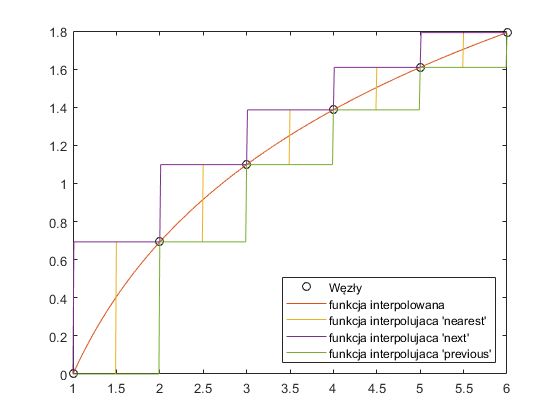

% Podstawowa interpolacja to interpolacja liniowa:
clear all;

% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 
x = [1:1:6];
y = log(x);           %zatem funkcja interpolowana to ln(x)
xx = [min(x):0.01:max(x)];

%Zwróć uwagę, że składnia jest trochę inna. Tutaj nie mamy jawnie
%współczynników, tylko od razu wynik interpolacji
yy = interp1(x,y,xx,'nearest');
yy1 = interp1(x,y,xx,'next');
yy2 = interp1(x,y,xx,'previous');

%Narysujmy funkcję, węzły i funkcje interpolujące
plot(x,y,'ko');
hold on;
plot(xx,log(xx));
plot(xx,yy)
plot(xx,yy1)
plot(xx,yy2)
hold off;
legend("Węzły",...
       "funkcja interpolowana",...
       "funkcja interpolujaca 'nearest'",...
       "funkcja interpolujaca 'next'",...
        "funkcja interpolujaca 'previous'", 'Location','southeast');
title("Interpolacja funckjami 'schodkowymi'");

 

Oraz cała gama różnych splineów wielomianowych:

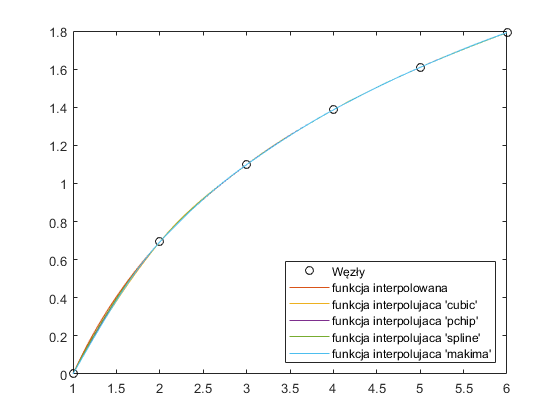

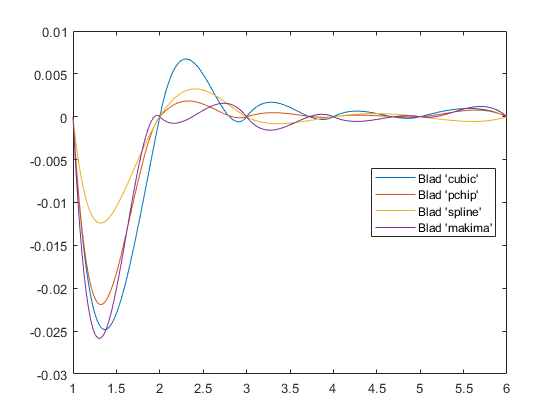

% Podstawowa interpolacja to interpolacja liniowa:
clear all;

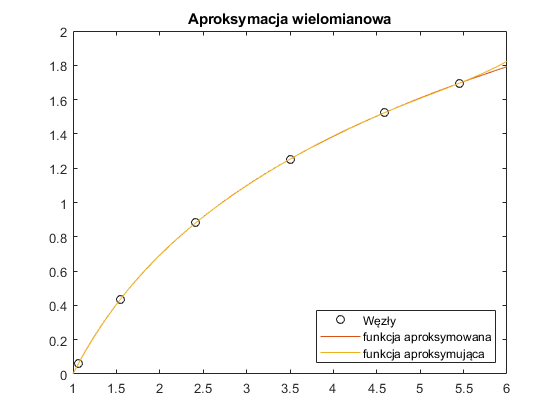

% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 
x = [1:1:6];
y = log(x);           %zatem funkcja interpolowana to ln(x)
xx = [min(x):0.01:max(x)];

%Zwróć uwagę, że składnia jest trochę inna. Tutaj nie mamy jawnie
%współczynników, tylko od razu wynik interpolacji
yy = interp1(x,y,xx,'cubic');       %klasyczny spline wielomianem 3 stopnia
yy1 = interp1(x,y,xx,'pchip');      %modyfikacja powyższej metody w celu zachowania kształtu funkcji oryginalnej więcej w [1]
yy2 = interp1(x,y,xx,'spline');     %kolejna modyfikacja klasycznego spline kubicznego patrz [1]
yy3 = interp1(x,y,xx,'makima');     %rodzaj interpolacji wielomianowej zmodyfikowanej tak, żeby dobrze oddawać płaskie części przebiegów [2-3]

blad = yy-log(xx);
blad1 = yy1-log(xx);
blad2 = yy2-log(xx);
blad3 = yy3-log(xx);

%Narysujmy funkcję, węzły i wielomian interpolujący
plot(x,y,'ko');
hold on;
plot(xx,log(xx));
plot(xx,yy)
plot(xx,yy1)
plot(xx,yy2)
plot(xx,yy3)
hold off;
legend("Węzły",...
       "funkcja interpolowana",...
       "funkcja interpolujaca 'cubic'",...
       "funkcja interpolujaca 'pchip'",...
       "funkcja interpolujaca 'spline'",...
       "funkcja interpolujaca 'makima'", 'Location','southeast');

plot(xx,blad)
hold on;
plot(xx,blad1)
plot(xx,blad2)

plot(xx,blad3)
hold off;
legend("Blad 'cubic'",...
       "Blad 'pchip'",...
       "Blad 'spline'",...
       "Blad 'makima'", 'Location','east');
title("Błędy różnego rodzaju interpolacji wielomianowych");
%Ponownie pobaw się ilością węzłów i funkcjami, żeby zobaczyć omawiane na
%wykładzie efekty numeryczne

 

Większość metod zaimplementowanych w ramach funkcji ***interp1()*** może być wywołana również w ramach dedykowanych funkcji takich jak:

- ***spline()***

- ***pchip()***

- ***makima()***

## **OPTYMALNY DOBÓR POŁOŻENIA WĘZŁÓW**

Na laboratorium możesz zostać poproszony o zaimplementowanie optymalnego doboru węzłów interpolacji dla podanego przedziału. Z wykładu wynika, że jest to dobór węzłów zaproponowany przez Czebyszewa. W MATLAB nie jest to jawnie zaimplementowane, więc należy to zaimplementować samemu

% Przykładowa interpolacja  za pomocą węzłów Czebyszewa
clear all;
% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 

%Rozkład węzłów zgodnie z zerami wielomianów Czebyszewa



$$x_{jc}=\frac{\left(\left(b-a\right)cos\left(\frac{(2j+1)\pi}{2N+2}\right)+a+b\right)}{2} $$
        
$$ j=0,1,2,\dots ,N  $$


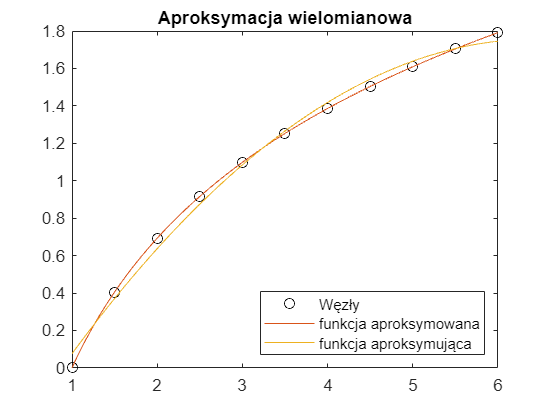

a=1; b=6; N=6;
j = [1:1:N];
x_czeb = ( (b-a).*cos(((2.*j+1).*pi)/(2.*N+2))+a+b )/2;
y = log(x_czeb);           %zatem funkcja interpolowana to ln(x)

%Wyliczenie współczynników wielomianu interpolacyjnego
wsp = polyfit(x_czeb,y,numel(x_czeb)-1);

%Chcemy teraz narysować funkcję interpolującą, ale również poza węzłami
%więc musze stworzyć nowy wektor x, gęstszy używany do rysowania
xx = [a:0.01:b];
yy = polyval(wsp,xx);


%Narysujjmy funkcję, węzły i wielomian aproksymujący - w tym przypadku 2
%stopnia
plot(x_czeb,y,'ko');
hold on;
plot(xx,log(xx));
plot(xx,yy)
hold off;

%Na koneic trochę opisu co jest co
legend("Węzły", "funkcja aproksymowana", "funkcja aproksymująca", 'Location','southeast')
title("Aproksymacja wielomianowa");

 

## APROKSYMACJE

Podstawowe aproksymacje wielomianowe powstają w analogiczny sposób jak interpolacje (w sensie sposobu budowy układu równań liniowych), dlatego może do ich tworzenia zostać użyta znana już funkcja ***polyfit()*** wywołanej z innym zestawem parametrów wejściowych. 

clear all;
% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 
x = [1:0.5:6];
y = log(x);           %zatem funkcja interpolowana to ln(x)

%Wyliczenie współczynników wielomianu interpolacyjnego
wsp = polyfit(x,y,2);

%Chcemy teraz narysować funkcję interpolującą, ale również poza węzłami
%więc musze stworzyć nowy wektor x, gęstszy używany do rysowania
xx = [min(x):0.001:max(x)];
yy = polyval(wsp,xx);

%Narysujjmy funkcję, węzły i wielomian aproksymujący - w tym przypadku 2
%stopnia
plot(x,y,'ko');
hold on;
plot(xx,log(xx));
plot(xx,yy)
hold off;

%Na koneic trochę opisu co jest co
legend("Węzły", "funkcja aproksymowana", "funkcja aproksymująca", 'Location','southeast')
title("Aproksymacja wielomianowa");
%Policzmy błąd aproksymacji - oczywiście poza węzłami bo w węzłach nas nie
%interesuje bo z definicji problemu wynosi 0:

%Skrypt jest zaimplementowany w automatyczny sposób, możesz pobawić się
%funkcjami i ilością węzłów. Zwróć uwagę na pojawiające się warningi
%MATLABA. Czy potrafisz powiedzieć o czym informują?

 

## APROKSYMACJA GAUSSOWSKA

Aproksymacja gaussowska jest również rodzajem aproksymacji wielomianowej. Aproksymacja gaussowska służy głównie jako baza do rozwiazywania problemów związanych z całkowaniem i przetwarzaniem sygnałów, gdzie pozwala na uzyskanie nieosiągalnych innymi metodami właściwości metodom ją wykorzystujących. W zakresie całkowania będziemy o tym mówili na wykładzie. Konsekwencją tego jest fakt, że w MATLAB nie ma funkcji implementujących samą aproksymację gaussowską (są one silnie zintegrowane z funkcjami całkującymi i funkcjami przetwarzającymi sygnały). Dlatego metody takie trzeba by implementować samemu "na piechotę". Nie będziemy robić tego na zajęciach z powodu braku czasu na laboratorium. Niemniej aproksymacje gaussowskie są bardzo ważne w zaawansowanym przetwarzaniu sygnałów. Dlatego polecam ściągnąć i zapoznać się z gotowymi implementacjami różnych aproksymacji opartych o wielomiany ortogonalne opracowanymi przez V. Karskiego [4] dostępnymi pod adresem: [link](https://www.mathworks.com/matlabcentral/fileexchange/69956-orthogonalpolynomials).

Są tam dostępne podobne LiveScripty pozwalające na interaktywną pracę z tym zagadnieniem.

## REGRESYJNE METODY APROKSYMACJI

Problem aproksymacji można przedstawić jako szczególny przypadek bardziej ogólnego problemu czyli regresji. W związku z tym do rozwiązania problemu aproksymacji można użyć metod optymalizacyjnych w taki sam sposób jak w problemie regresji. Regresji nie omawiamy na wykładzie podstawowym, ale warto znać taką możliwość. W problemie regresji ogólnie szukamy współczynników pewnej funkcji - modelu które najlepiej odzwierciedlają zbiór danych punktów wejściowych (x,y). Metody numeryczne stosowane do tego zagadnienia są to tzw. metody optymalizacyjne, o których wspominaliśmy w trakcie laboratorium z równań nieliniowych. Metody te szukają zera funkcji nazywanej funkcją celu.

Zastosowanie metod regresyjnych do problemu aproksymacji zakłada:

1. Przyjęcie jakiegoś modelu

2. Określenie funkcji celu: 

W przypadku regresji średniokwadratowej odpowiadającej aproksymacji średniokwadratowej jest to najczęściej:

3. Przyjęcie jakiejś konkretnej metody optymalizacji np. metody regionów zaufania, albo metody Levenberga-Marquarta


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


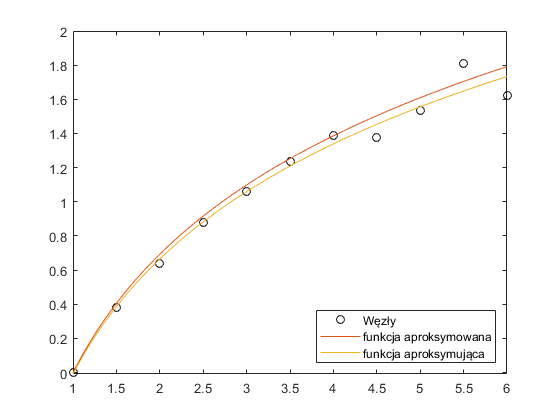

clear all;

% Dane wejściowe do zagadnienia - wektory ze współrzędnymi x i y punktów 
xdata = [1:0.5:6];
ydata = log(xdata);           %zatem funkcja aproksymowana to ln(x)

% W problemie regresji zakładamy, że dane wejściowe są zaszumione, zatem
% dodajmy szum na poziomie 10%:
ydata = ydata + 2.*(rand(1,numel(ydata))-0.5)*0.1.*ydata;

%Definicja modelu  y = a*ln(b*x)
model_function = @(wsp_mod, xdata) wsp_mod(1).*log(wsp_mod(2).*xdata);

%Punkt startowy
wsp_mod0=[1,1];      %punkt startowy (metoda jako niewiadome traktuje współczynnikim modelu)

%Obliczamy współczynniki modelu za pomocą funkcji lsqcurvefit()
[wsp_mod,resnorm,residual,exitflag,output] = lsqcurvefit(model_function,wsp_mod0,xdata,ydata);

% W zmiennej wsp_mod mamy określone współczynniki
% W zmiennej exitflag informacje czy udało się znaleźć rozwiązanie (są to
% procedury iteracyjne)
% W zmiennej output mamy informacje diagnostyczne

%Wektor do rysowania:
xx = [min(xdata):0.001:max(xdata)];


%Narysujmy funkcję, węzły i funkcję aproksymującą
plot(xdata,ydata,'ko');
hold on;
plot(xx,log(xx));
plot(xx,model_function(wsp_mod,xx));
hold off;

%Na koniec trochę opisu co jest co
legend("Węzły", "funkcja aproksymowana", "funkcja aproksymująca", 'Location','southeast')
title("Metody optymalizacyjne - regiony zaufania");

 

Podobnie jak większość funkcji w MATLAB funkcja ***lsqcurvefit()*** jest wraperem dla większej ilości metod. Definiuje ona funkcji celu, ale to jaka metoda optymalizacyjna zostanie użyta zależy od ustawień. Ustawienia dokonujemy na analogicznej zasadzi jak omawiana w przypadku laboratorium z metod nieliniowych:


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


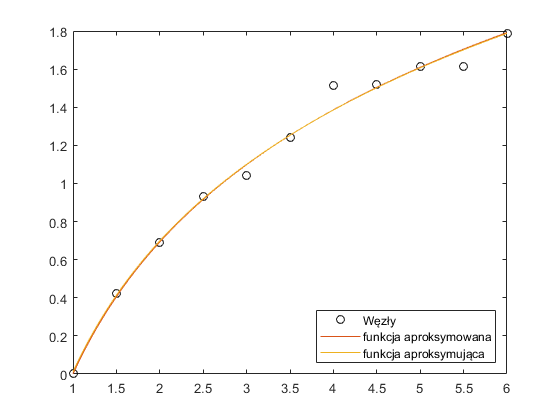

clear all;

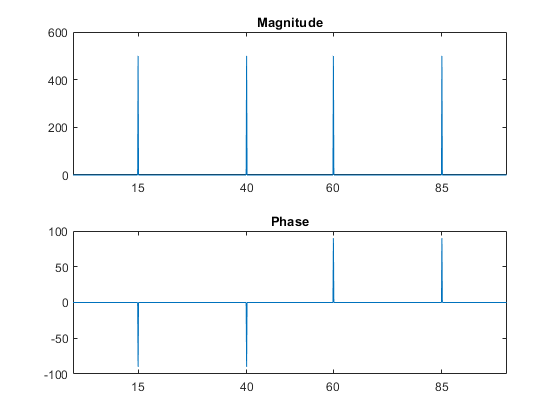

%Przygotowujemy obiekt z opcjami dla fsolve()
% - jako pierwszy argument podajemy nazwę funkcji 'lsqcurvefit'
% - potem podajemy pary >Nazwa opcji<, >Wartość<
%Przykładowo jeżeli chcemy ustawić dokładność na 1e-12 oraz wybrać metodę
%Levenberga-Marquarta
options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt','FunctionTolerance',1e-12,'OptimalityTolerance',1e-12);

% W tym wypadku mamy dwie opcje 'FunctionTolerance' ustawia dokładność w
% ewaluacji wartości funkcji (skoro szukamy zera jest to dokładność
% wartości funkcji w okolicy zera), 'OptimalityTolerance' to inna miara
% dokładności specyficzna dla tych metod więcej dla zainteresowanych w
% dokumentacji MATLAB pod hasłem "First-Order Optimality Measure"
            
xdata = [1:0.5:6];
ydata = log(xdata);           %zatem funkcja aproksymowana to ln(x)

% W problemie regresji zakładamy, że dane wejściowe są zaszumione, zatem
% dodajmy szum na poziomie 10%:
ydata = ydata + 2.*(rand(1,numel(ydata))-0.5)*0.1.*ydata;

%Definicja modelu  y = a*ln(b*x)
model_function = @(wsp_mod, xdata) wsp_mod(1).*log(wsp_mod(2).*xdata);

%Punkt startowy
wsp_mod0=[1,1];      %

%Obliczamy współczynniki modelu za pomocą funkcji lsqcurvefit()
[wsp_mod,resnorm,residual,exitflag,output] = lsqcurvefit(model_function,wsp_mod0,xdata,ydata);

% W zmiennej wsp_mod mamy określone współczynniki
% W zmiennej exitflag informacje czy udało się znaleźć rozwiązanie (są to

% procedury iteracyjne)
% W zmiennej output mamy informacje diagnostyczne

%Wektor do rysowania:
xx = [min(xdata):0.001:max(xdata)];


%Narysujmy funkcję, węzły i funkcję aproksymującą
plot(xdata,ydata,'ko');
hold on;
plot(xx,log(xx));
plot(xx,model_function(wsp_mod,xx));
hold off;

%Na koniec trochę opisu co jest co
legend("Węzły", "funkcja aproksymowana", "funkcja aproksymująca", 'Location','southeast')
title("Metody optymalizacyjne - Levenberg-Marquart");
% Powinniśmy uzyskać trochę lepszy wynik bo zwiększyliśmy wymagania
% dokładności i zmieniliśmy metodę na trochę bardziej zaawansowaną

 

## TRANSFORMATA FOURIERA

W elektronice szczególną rolę odgrywa transformata Fouriera, która jest szczególnym rodzajem interpolacji za pomocą funkcji nie wielomianowych. Podstawowa transformata Fouriera obliczana za pomocą algorytmu FFT jest zaimplementowana za pomocą funkcji ***fft()***.

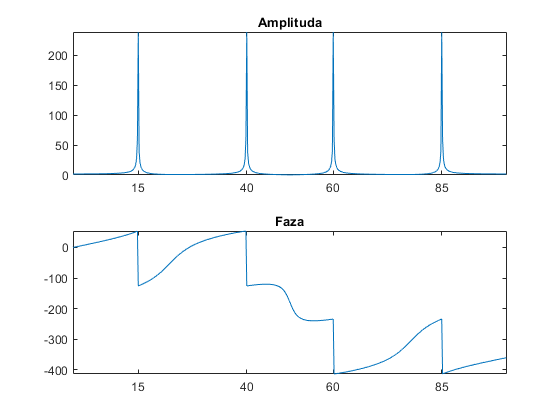

% Załóżmy nasze dane wejściowe
t = 0:1/100:10-1/100;                     % wektor czasu

x = sin(2*pi*15*t) + sin(2*pi*40*t);      % wektor wartości sygnału

% Obliczamy DFT przy pomocy algorytmu FFT (pamiętając o jego
% ograniczeniach)
y = fft(x);                               
m = abs(y);                               % Widmo amplitudowe
y(m<1e-6) = 0;                            % Do obliczenia widma fazowego musimy wyeliminować szum 
p = unwrap(angle(y));                     % Widmo fazowe

%Wykreślamy widma:

f = (0:length(y)-1)*100/length(y);        % Wektor częstotliwości

subplot(2,1,1)
plot(f,m)
title('Magnitude')
ax = gca;
ax.XTick = [15 40 60 85];

subplot(2,1,2)
plot(f,p*180/pi)
title('Phase')
ax = gca;
ax.XTick = [15 40 60 85];

 

Przy takiej implementacji MATLAB domyślnie stosuje maksymalną możliwą ilosć punktów (oczywiście będącą potęgą dwójki). Możemy jednak kazać MATLABowi obliczyć konkretnie n-punktową transformatę:

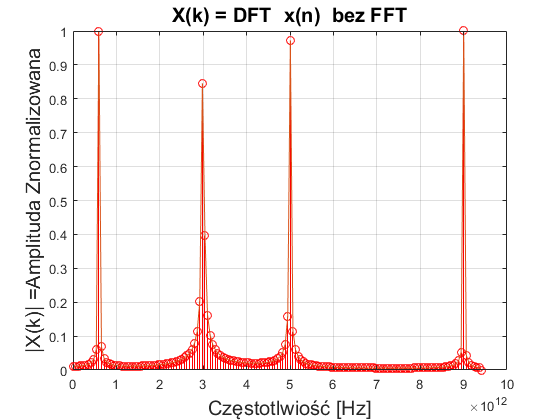

% Załóżmy nasze dane wejściowe
t = 0:1/100:10-1/100;                     % wektor czasu
x = sin(2*pi*15*t) + sin(2*pi*40*t);      % wektor wartości sygnału

% Obliczamy DFT przy pomocy algorytmu FFT (pamiętając o jego
% ograniczeniach)
n = 512;
y = fft(x,n);                               
m = abs(y);                               % Widmo amplitudowe
y(m<1e-6) = 0;                            % Do obliczenia widma fazowego musimy wyeliminować szum 
p = unwrap(angle(y));                     % Widmo fazowe

%Wykreślamy widma:

f = (0:length(y)-1)*100/length(y);        % Wektor częstotliwości

subplot(2,1,1)
plot(f,m)
title('Amplituda')
ax = gca;
ax.XTick = [15 40 60 85];

subplot(2,1,2)
plot(f,p*180/pi)
title('Faza')
ax = gca;
ax.XTick = [15 40 60 85];

%Możesz pobawić się ustawieniami. Czy jesteś w stanie wyjaśnić różnice
%między otrzymywanymi wynikami znając mechanikę działania FFT i DFT?


Na sam koniec warto zobaczyć jakie są różnice wydajności w obliczaniu FFT i DFT z definicji bazując na kodzie udostępnionym w [5]:

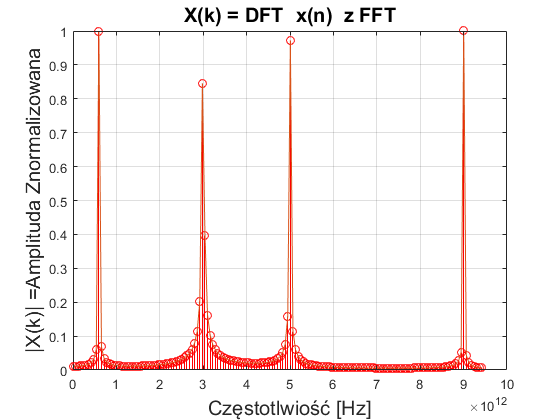

close all; clear all; clc;

R = 1e12;                % Zakres częstotliwości składowych, 
                         % np. 3 = kHz, 6 = MHz, 9 = GHz, 12 = THz
f = [3,5,9,0.6]'*R;      % Częstotliwości składowe sygnału

% Te zależności wynikają z teorii Nyquista:
fs = 2.1*max(f);          %  Częstotliwość próbkowania > 2 * maksymalna częstotliwość
Ts = 1/fs;

t = 0:Ts:10/min(f)+Ts;    
N = length(t);            
fa = (0:N/2)*0.5*fs/(N/2);    



 Czas w [s] - obliczenia bez FFT = 0.044779 

xs = sin(2*pi*f*t); % macierz sinusoidalnych składowych poszczególnych częstotliwości


 Czas w [s] - obliczenia z = 0.183378 


 Algorytm FFT wykonał się 0.24 razy szybciej.

x = sum(xs);        % Sumujemy nasze składowe

%Będziemy mierzyć czas wykonania więc:
t1 = tic;           %startujemy pomiar czasu
[X,dl,mx] = dft_definitive(x,N);
t1_end = toc(t1);   %kończymy pomiar czasu

% A teraz dla wbudowanego algorytmu FFT
t2 = tic;
y = abs(fft(x));
y = y/max(y);
t2_end = toc(t2);

%Trochę dalszego przetwarzania sygnałów do rysowania:

counter1 = 1;     
counter2 = 1;     
for k = 1:length(dl)                            
   if (mx(k) >= 0.5) 
     fe1 (counter1) = k;  
     counter1 = counter1+1;
   end
   
   if (y(k) >= 0.5)
    fe2 (counter2) = k;     
     counter2 = counter2+1;
   end
end

%Wyrysujmy wyniki (znormalizowane żeby dało się łatwo porównać)
figure(1)
stem(fa,mx(dl),'ro');    % Próbki w dziedzinie f
hold on;
plot(fa,mx(dl));         % Linia łącząca
grid on;

xlabel('Częstotlwiość [Hz]','FontSize',15);
ylabel('|X(k)| =Amplituda Znormalizowana','Fontsize',15);
title('X(k) = DFT { x(n) } bez FFT', 'FontSize',15);


figure(2)
stem(fa,y(dl),'ro');    % Próbki w dziedzinie f
hold on;
plot(fa,y(dl));         % Linia łącząca
grid on;

xlabel('Częstotlwiość [Hz]','FontSize',15);
ylabel('|X(k)| =Amplituda Znormalizowana','Fontsize',15);
title('X(k) = DFT { x(n) } z FFT', 'FontSize',15);

%Obliczenie czasu wykonania:

fprintf('\n Czas w [s] - obliczenia bez FFT = %f ',t1_end);
fprintf('\n Czas w [s] - obliczenia z = %f ',t2_end);
fprintf('\n Algorytm FFT wykonał się %0.2f razy szybciej.', t1_end/t2_end);

% Spróbuj dodać składowych sygnału i/lub próbek i zobacz jak to wpływa na
% czas wykonania algorytmów i wyniki.

 

## FUNKCJE

% Copyright (c) 2015, Praveen Ranganath
% All rights reserved.
% 
% Redistribution and use in source and binary forms, with or without
% modification, are permitted provided that the following conditions are
% met:
% 
%     * Redistributions of source code must retain the above copyright
%       notice, this list of conditions and the following disclaimer.
%     * Redistributions in binary form must reproduce the above copyright
%       notice, this list of conditions and the following disclaimer in
%       the documentation and/or other materials provided with the distribution
% 
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS"
% AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE
% IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE
% ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT OWNER OR CONTRIBUTORS BE
% LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR
% CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF
% SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS
% INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN
% CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE)
% ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE
% POSSIBILITY OF SUCH DAMAGE.


function [X,dl,mx] = dft_definitive(x,N)
X = zeros(1,N);                     % Wynik transformaty, X(k) = DFT { x(n) }
powers = (-2*pi*1j/N)*(0:N-1);      % Definicyjny wzór na poszczególne potęgi

for k = 1:N/2                       % N/2-1
    X(k) = x* exp((k-1)*powers');   % X(k) = sum { x(n)exp(-2*pi*i*k*n/n) }
                                    %        k=0
end

dl = 1:round(N/2);               
mx = abs(X)/max(abs(X));            % Normalizacja
end

[1] https://blogs.mathworks.com/cleve/2012/07/16/splines-and-pchips/

[2] Akima, Hiroshi. "A new method of interpolation and smooth curve fitting based on local procedures." *Journal of the ACM (JACM)* , 17.4, 1970, pp. 589-602.

[3] Akima, Hiroshi. "A method of bivariate interpolation and smooth surface fitting based on local procedures." *Communications of the ACM* , 17.1, 1974, pp. 18-20.

[4] Vilem Karsky (2021). OrthogonalPolynomials (https://www.mathworks.com/matlabcentral/fileexchange/69956-orthogonalpolynomials), MATLAB Central File Exchange. Retrieved March 23, 2021. 

[5]Praveen Ranganath (2021). Computation of DFT - WIth and without using FFT  (https://www.mathworks.com/matlabcentral/fileexchange/52485-computation-of-dft-with-and-without-using-fft), MATLAB Central File Exchange. Retrieved March 23, 2021. 

Warszawa, 23.03.2021 r.                                                                                                           **© **K. Król

Sem. 21L